Climb rate

Ts_hev = 1/100;
% Requirments
Mp = 0.2

Mp = 0.2000

tr = 1;
zeta = sqrt((log(Mp)^2)/(log(Mp)^2+pi^2))

zeta = 0.4559

wn = 1.8/(tr);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)]

p_s_want =   -0.8207 + 1.6020i
  -0.8207 - 1.6020i


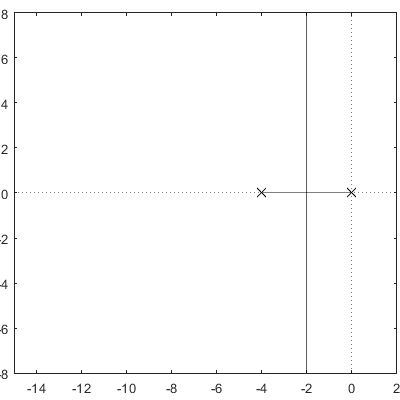


% Plant
A_hev = [-1/t_P,  0, 0;
          1/m(1), 0, 0;
          0,      1, 0];

b_hev = [1/t_P; 0; 0];
c_climb = [0, 1, 0];
d_climb = 0;

sysC_climb = ss(A_hev,b_hev,c_climb,d_climb);
% sysD_climb = c2d(sysC,Ts_hev,'zoh');
black_rlocus(sysC_climb,[])


Ki = 21.791

Ki = 21.7910

Kp = Ki*3.6

Kp = 78.4476

% Ki = 20

C_climb = pid(Kp,Ki,0,0);
% [C_climb,info] = pidtune(sysD_climb,'PI')
sysFB = feedback(C_climb*sysC_climb,1);
P_cl = rlocus(sysFB,1)

P_cl =   -1.8425 + 2.2913i
  -1.8425 - 2.2913i
  -0.3151 + 0.0000i


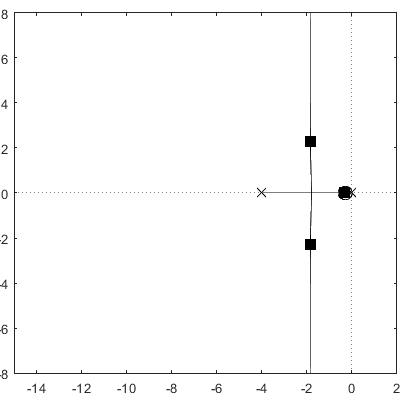

black_rlocus(C_climb*sysC_climb,P_cl)

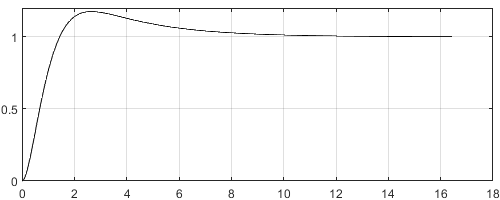


black_step(sysFB)


% Equivalent plant
A_clm = [A_hev-b_hev*C_climb.Kp*c_climb, b_hev*C_climb.Ki;
         -c_climb              , 0];
b_clm = [b_hev*C_climb.Kp;1];


Altitude

% Requirments
zeta = 1

zeta = 1

ts2 = 2;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)]

p_s_want =     -2
    -2



p_z_want = exp(p_s_want*Ts_hev)

p_z_want =     0.9802
    0.9802



% Plant
c_alt = [0,0,1,0];
d_alt = 0;

sysC_alt = ss(A_clm,b_clm,c_alt,d_alt);
% sysD_alt = c2d(sysC,Ts_hev,'zoh');

Kp = 0.45

Kp = 0.4500

C_alt = pid(Kp,0,0,0)

C_alt =
 
  Kp = 0.45
 
P-only controller.



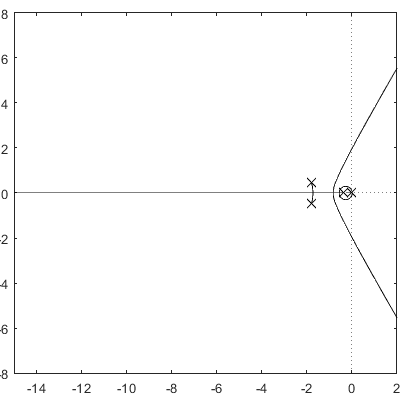

% [C_alt, info] = pidtune(sysD_alt,'P')
sysFB = feedback(C_alt*sysC_alt,1);

black_rlocus(sysC_alt,[])

P_cl = rlocus(sysFB,1)

P_cl =   -2.9545 + 0.0000i
  -0.3940 + 1.2066i
  -0.3940 - 1.2066i
  -0.2575 + 0.0000i


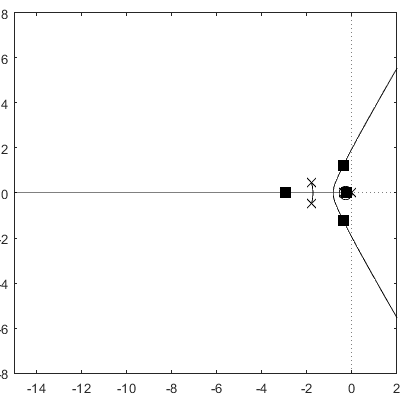

black_rlocus(C_alt*sysC_alt,P_cl)

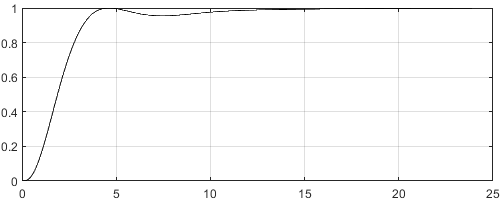

% black_rlocus_fine(C_alt*sysD_alt,P_cl)
black_step(sysFB)